# Smile Detection Implementation

load classdata_train.mat
train_data = grayfaces;
y_train = y;
clear grayfaces y

Using the provided starter code, I begin preparing the data for analysis.

First, we vectorize the images, and combine them into one large matrix.

train_vec = reshape(train_data,size(train_data,1)*size(train_data,2),size(train_data,3));

Next, we subtract the means and normalize the training and test images.

train_vec_ms=(train_vec-mean(train_vec,2))./vecnorm(train_vec-mean(train_vec,2));

With the prep done, we now move onto determining the weights of the marix. We will do so starting by using a trick dervied from SVD - let the training data be called A. We will then find the non-trivial eigenvalues of A by determining the eigenvalues of A^T * A; letting v be the eigenvectors of A^T * A, the associated eigenvectors for A can be found by A * v.

ata = train_vec_ms' * train_vec_ms;
[ata_v,ata_d] = eig(ata);
ata_v = flip(ata_v,2);
flip(mean(ata_d)' * size(ata_d,1)); % Flipping allows us to more easily select the largest eigenvalues and associated eigenvectors
v = train_vec_ms * ata_v;

With these both defined, we can now solve for our weight matrix, *w.*

w = train_vec_ms' * v;

With the weights vector now defined, we can test the effectiveness of this smile recognition process:

First, we load the test data.

load classdata_test.mat
test_data = grayfaces;
y_test = y;
clear grayfaces y

We now create the test vectors, following the same process done for the training data.

test_vec = reshape(test_data, size(test_data,1)*size(test_data,2), size(test_data,3));
test_vec_ms=(test_vec-mean(test_vec,2))./vecnorm(test_vec-mean(test_vec,2));

Then, we classify it using the weight vector!

foo = test_vec_ms(:,3)' * v;

Now we compare the results to the existing weight matrix, by checking how closely the weight vector matches each column in the weight matrix - as we are doing a floating point comparison, we use the *eps* value as a tolerance level. The higher the output percentage, the better the match.

comparison = sqrt(mean((w - foo).^2,2));
[acc, face] = min(comparison);
acc, face

acc = 0.0565

face = 1

Now what we can do is automatically generate the face's name as well, using the provided information.

comp_string = "The face of " + y_test.name{1,3} + " is identified as the face of " + y_train.name{1, face} + ". " + ...
    "The accuracy of the match is about " + round((mean(w(face,:) - foo < eps))*100,1) + "%.";
comp_string

comp_string = "The face of alexandra_maycock is identified as the face of alexandra_maycock. The accuracy of the match is about 48.1%."

The last step is upon us! With all the background work established, we will now move onto making a consolidated function that handles all of this work and compiles it together. First, is the data handling.

clearvars
close all
load('/home/sswaminathan/olin_share/Semester2/QEA/FacesModule/Night7/classdata_train.mat')
train_data = grayfaces;
y_train = y;
clear grayfaces y
load('/home/sswaminathan/olin_share/Semester2/QEA/FacesModule/Night7/classdata_test.mat')
test_data = grayfaces;
y_test = y;
clear grayfaces y

tic
classifier(train_data, test_data, y_train, y_test, 50, 300)
toc

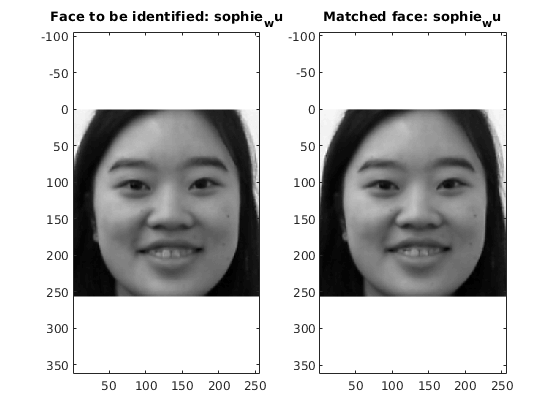

comp_string = "The face of sophie_wu is identified as the face of sophie_wu. The accuracy of the match is about 6.4%."

ans = 0.0644

accV = ones([106,1]);
tic

for i=1:106

Elapsed time is 0.279610 seconds.


    accV(i) = classifier(train_data, test_data, y_train, y_test, i, 0);
end
toc
figure(2)
plot(1:106,accV,".")
title('Accuracy of classifier for different number of basis eigenfaces')
xlabel('Number of basis eigenfaces')

Elapsed time is 40.387305 seconds.


ylabel('Accuracy (%)')
axis([0 110 0 1.1])

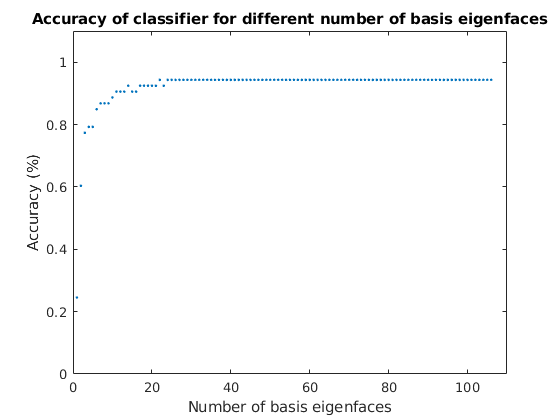

function [acc] = classifier(train_data, test_data, y_train, y_test, M, num)
    [w, v] = trainer(train_data, M); % train the datasets and produce eigenfaces and associated weight matrix
    input_data = test_init(test_data); % vectorize input images
    if num > 0

        [acc, face] = face_match(input_data(:,num), v, w); % Determine the face match (acc is a sham for now)
        comp_string = "The face of " + y_test.name{1,num} + " is identified as the face of " + y_train.name{1, face} + ". " + ...
    "The accuracy of the match is about " + round(acc*100,1) + "%."; % Make a nice string to explain the match
        figure(1) % Plot time
        subplot(1,2,1)
        imagesc(test_data(:,:,num))
        colormap('gray')
        axis equal
        title("Face to be identified: " + y_test.name{1, num})
        subplot(1,2,2)
        imagesc(train_data(:,:,face))
        colormap('gray')
        axis equal
        title("Matched face: " + y_train.name{1, face})
        comp_string % Display string time
    else
        acc = 0; % Initialize accuracy variable
        for i = 1:53
            j = i * 6 - 3; % Pick the 6th image per person
            [euc, face] = face_match(input_data(:,j), v, w); % Determine face match for image
            if mean(string(y_test.name{1,j}) == string(y_train.name{1,face})) == 1 % Check if matched image name and input image name match
                acc = acc + 1; % Increment the number of correct matches
            end
        end
        acc = acc / 53; % Generate percentage value of accuracy
    end
end

Here we define all the helper functions to the main method seen above.

This function will return the weight matrix and eigenfaces from training.

function [w, v] = trainer(train_data, M) 
    train_vec = reshape(train_data,size(train_data,1)*size(train_data,2),size(train_data,3)); % reshape training images into vectors
    train_vec_ms=(train_vec-mean(train_vec,2))./vecnorm(train_vec-mean(train_vec,2)); % subtract the mean
    ata = train_vec_ms' * train_vec_ms; % find the eigenvalues of the covariance matrix
    [ata_v,ata_d] = eig(ata);
    ata_v = flip(ata_v,2);
    flip(mean(ata_d)' * size(ata_d,1)); % Flipping allows us to more easily select the largest eigenvalues and associated eigenvectors
    v = train_vec_ms * ata_v; % find the eigenvectors of the covariance matrix
    v = v(:,1:M); % Select the first M eigenvectors corresponding to the first M largest eigenvalues to be our eigenfaces
    w = train_vec_ms' * v; % Find the weight matrix from the training data and eigenfaces
end

This function initializes the test data.

function [test_vec_ms] = test_init(test_data) 
    test_vec = reshape(test_data, size(test_data,1)*size(test_data,2), size(test_data,3)); % Transform the test_data into vectorized images
    test_vec_ms=(test_vec-mean(test_vec,2))./vecnorm(test_vec-mean(test_vec,2)); % Subtract out the mean
end

This function will return the index of the matched face, as well as the accuracy of the match.

function [acc, idx] = face_match(face, eigfaces, w)
    foo = face' * eigfaces; % Use the eigenfaces to determine the weight vector corresponding to the input
    [acc, idx] = min(sqrt(mean((w - foo).^2,2))); % Find the training image that has the least euclidean distance from the input
end